# IonMonger Lite

This live script is intended as a simple version of IonMonger that allows users to run basic simulation protocols without any expertise in MATLAB. The numerical solver used here is identical to the full version but users do not need to edit and format a parameters file in order to run simulations. Click 'Run' to begin the simulation. For the simplest user experience, ensure 'Hide Code' is selected under the 'VIEW' tab in MATLAB.

% This is a live script to enable users to run simple simulations without
% the need for any knowledge of MATLAB. This script replaces both
% parameters.m and master.m, compiling a parameters structure and calling
% numericalsolver.m to perform the simulation. Also included are some
% plotting functions to plot the simulation output.

clear;

% configure format settings for text
s = settings;
s.matlab.fonts.editor.normal.Size.PersonalValue = 14;
s.matlab.fonts.editor.normal.Name.PersonalValue = 'Calibri';
s.matlab.fonts.editor.title.Color.PersonalValue = [0 0 255 1];
s.matlab.fonts.editor.title.Style.PersonalValue = {'bold'};

tic;
starttime = datestr(now);
reset_path();

workfolder  = './Data/'; % the folder to which data will be saved

 

**Output plots**

If these boxes are checked, the corresponding plot will be generated and displayed below the live script.

plotoptions = [false,... % current-time plot
    true,... % current-voltage plot
    true,... % experimental protocol plot
    false ,... % electric potential during sweep
    false ,... % electron density
    false ,... % hole density
    false ,... % anion vacancy density
    ];

% --- Parameter definitions ---


Verbose = false; % Verbose is set to false for simplicity but can be turned on 
% for debugging purposes
Stats       = 'off'; % ode15s option to output stats, either 'on' or 'off'
OutputFcn   = 'PrintVolt'; % ode15s optional message function, choose
% either 'PrintVolt' or 'PrintTime' (which can be found in Code/Common/)
% note that this option overwrites the previous two if Verbose=false
UseSplits   = true; % set this to false to make a single call to ode15s

% Resolution and error tolerances
N    = 400; % Number of subintervals, with N+1 being the number of grid points
rtol = 1e-6; % Relative temporal tolerance for ode15s solver
atol = 1e-10; % Absolute temporal tolerance for ode15s solver

% Physical constants
eps0  = 8.854187817e-12;  % permittivity of free space (Fm-1)
q     = 1.6021766209e-19; % charge on a proton (C)
Fph   = 1.4e21;           % incident photon flux (m-2s-1)
kB    = 8.61733035e-5;    % Boltzmann constant (eVK-1)

## Parameter input

### Perovskite parameters


T = 298;       % temperature (K)
b = 4e-7;       % perovskite layer width (m)

b =      3.000000000000000e-07


epsp = 24.1*eps0;       % permittivity of perovskite (Fm-1)
alpha = 13000000;     % perovskite absorption coefficient (m-1)
Ec    = -3.7;      % conduction band minimum (eV)
Ev    = -5.4;      % valence band maximum (eV)
Dn    = 0.00017;    % perovskite electron diffusion coefficient (m2s-1)
Dp    = 0.00017;    % perovskite hole diffusion coefficient (m2s-1)
gc    = 8.1e+24;    % conduction band density of states (m-3)
gv    = 5.8e+24;    % valence band density of states (m-3)

### Ion **parameters**

N0    = 1.6e+25;        % typical density of ion vacancies (m-3)
D     = @(Dinf, EA) Dinf*exp(-EA/(kB*T)); % diffusivity relation
DIinf = 6.5e-8;        % high-temp. vacancy diffusion coefficient (m2s-1)
EAI   = 0.58;          % iodide vacancy activation energy (eV)
DI    = D(DIinf, EAI); % diffusion coefficient for iodide ions (m2s-1)


Direction of light

inverted = false; % choose false for a standard architecture cell (light
% entering through the ETL), true for an inverted architecture cell
% (light entering through the HTL)


### ETL parameters

dE    = 1e+24;    % effective doping density of ETL (m-3) (choose <gcE/20)
gcE   = 5e+25;    % effective conduction band DoS in ETL (m-3)
EcE   = -4;    % conduction band minimum in ETL (eV)
bE    = 1e-7;  % width of ETL (m)
epsE  = 10*eps0; % permittivity of ETL (Fm-1)
DE    = 0.00001;    % electron diffusion coefficient in ETL (m2s-1)


### HTL parameters

dH    = 1e+24;    % effective doping density of HTL (m-3) (choose <gvH/20)
gvH   = 5e+25;    % effective valence band DoS in HTL (m-3)
EvH   = -5.1;    % valence band maximum in HTL (eV)
bH    = 2e-7;  % width of HTL (m)
epsH  = 3*eps0;  % permittivity of HTL (Fm-1)
DH    = 0.000001;    % hole diffusion coefficient in HTL (m2s-1)


### Bulk recombination

tn    = 3e-9;    % electron pseudo-lifetime for SRH (s)
tp    = 3e-7;    % hole pseudo-lifetime for SRH (s)
beta  = 0;       % bimolecular recombination rate (m3s-1)


### Interface recombination

Recombination velocities should not exceed ~ 1e5.

betaE = 0;       % ETL/perovskite bimolecular recombination rate (m3s-1)
betaH = 0;       % perovskite/HTL bimolecular recombination rate (m3s-1)
vnE   = 100000;     % electron recombination velocity for SRH (ms-1)
vpE   = 10;      % hole recombination velocity for SRH (ms-1)
vnH   = 0.1;     % electron recombination velocity for SRH (ms-1)
vpH   = 100000;     % hole recombination velocity for SRH (ms-1)

%% Non-dimensionalise model parameters and save all inputs

% Compile all parameters into a convenient structure
vars = setdiff(who,{'params','vars'});
for i=1:length(vars), params.(vars{i}) = eval(vars{i}); end

% Non-dimensionalise the user-defined input parameters
warning('off','NoAuger:WarnID') % supress warning about Auger recombination
params = nondimensionalise(params);

% Unpack variables and functions needed in the rest of this function
[tstar2t, psi2Vap, Upsilon, Vbi] = struct2array(params, ...
    {'tstar2t','psi2Vap','Upsilon','Vbi'});


## Simulation protocol

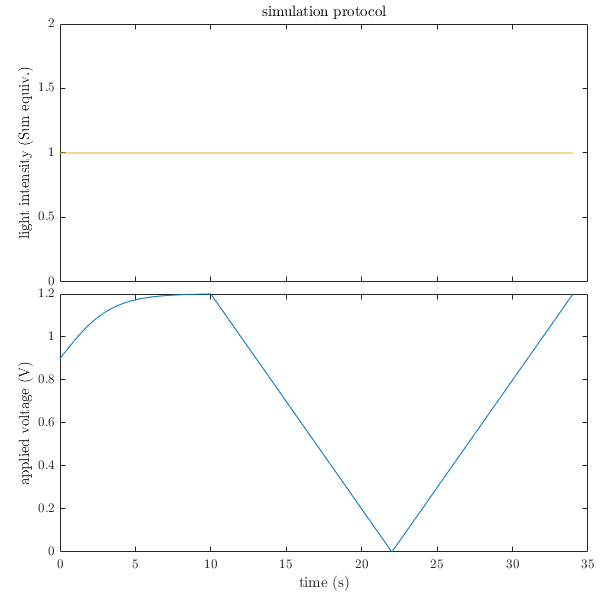

% In order to make use of construct_protocol.m, instructions must be given
% in a specific order and format. Please see the GUIDE.md. Otherwise one
% can specify their own dimensionless functions of time (light and psi),
% dimensionless vectors (time and splits) and option whether to findVoc.

% Light protocol (either {a single value} or a protocol including an
% initial value, set to 1 for measurements in the light, 0 in the dark)
light_intensity = {1};

% Voltage protocol (either {'open-circuit'}, {a single value} or a protocol
% beginning with either 'open-circuit' or an initial value, in Volts)
prot_vals = [Vbi, ...
    10,...
    1.2, ...
    0.1, ...
    0];
applied_voltage = ...
    {prot_vals(1), ... % steady-state initial value
    'tanh', prot_vals(2), prot_vals(3), ...
    'linear', prot_vals(3)/prot_vals(4), prot_vals(5), ...
    'linear', prot_vals(3)/prot_vals(4), prot_vals(3)};


% Choose whether the time points are spaced linearly or logarithmically
time_spacing = 'lin'; % set equal to either 'lin' (default) or 'log'


%% Create the simulation protocol and plot (if Verbose)

% Create the protocol and time points automatically, psi=(Vbi-Vap)/(2*kB*T)
[light, psi, time, splits, findVoc] = ...
    construct_protocol(params,light_intensity,applied_voltage,time_spacing);

% *** If defining one's own simulation protocol, define it here! ***

% Apply the options defined above
if inverted, inv = -1; else, inv = 1; end
if ~UseSplits, splits = time([1,end]); end

% Define the charge carrier generation function G(x,t)
G = @(x,t) light(t).*Upsilon./(1-exp(-Upsilon)).*exp(-Upsilon*(inv*x+(1-inv)/2));

if plotoptions(3) % plot simulation protocol
    if ishandle(99), clf(99); end; fig=figure(99);
    set(fig,'Units','Pixels','Position',[0 0 600 600])
    ax1 = axes('Position',[10, 53, 88, 43]/100);
    plot(tstar2t(time),light(time),'Color',[0.93 0.69, 0.13]);
    ax2 = axes('Position',[10, 8, 88, 43]/100);
    plot(tstar2t(time),psi2Vap(psi(time)));
    title(ax1,'simulation protocol','Interpreter','latex','FontSize',14)
    linkaxes([ax1,ax2],'x')
    xlabel(ax2,'time (s)','Interpreter','latex')
    ylabel(ax1,'light intensity (Sun equiv.)','Interpreter','latex')
    ylabel(ax2,'applied voltage (V)','Interpreter','latex')
    set(ax1,'TickLabelInterpreter','latex','XTickLabel',[],'FontSize',10)
    set(ax2,'TickLabelInterpreter','latex','FontSize',10)
end


%% Compile more parameters into the params structure
vars = setdiff(setdiff(who,fieldnames(params)),{'params','vars','i'});
for i=1:length(vars), params.(vars{i}) = eval(vars{i}); end

% Make the folder in which to save the output data (specified above)
if exist(workfolder,'dir')~=7, mkdir(workfolder); end


### Simulation status

The start and end time of the simulation will be displayed below. If the numerical solver encountered an error and could not return a solution, the error message will be displayed below.

fprintf('Computation started at %s\n', starttime);

Computation started at 08-Dec-2021 11:09:29



% Solve the equations
try
    sol = numericalsolver(params);
catch ME
    rethrow(ME)
end

disp('Simulation did not encounter any errors')

Simulation did not encounter any errors



% Save the data
save([params.workfolder,'simulation.mat'],'sol');

% Stop stopwatch and output nice message
fprintf('Completed simulation at %s, taking %s\n', ...
    datestr(now), secs2hms(toc) );

Completed simulation at 08-Dec-2021 11:09:33, taking 00:00:04


## Output plots

Any requested output plots will be displayed here. These plots can be edited and exported here or in a separate window by clicking the arrow in the top right of each figure.

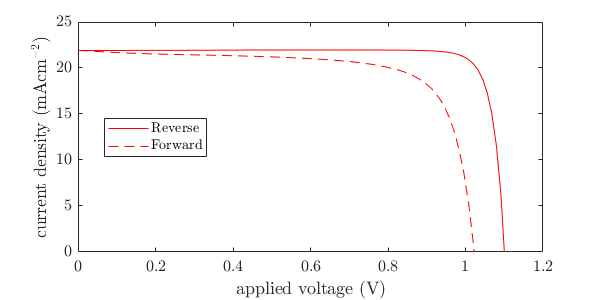


% --- plot the output ---

if plotoptions(1) % plot current against time
    figure()
    plot(sol.time,sol.J,'b')
    xlabel('time (s)','Interpreter','latex'); ylabel('current density (mAcm$^{-2}$)','Interpreter','latex');
    set(gcf,'Units','pixels','Position',[0 0 600 300])
    set(gca,'FontSize',12,'TickLabelInterpreter','latex')
end
if plotoptions(2) % plot current against voltage
    figure()
    i = 101:201; % exclude first section
    plot(sol.V(i),sol.J(i),'-r')
    hold on
    plot(sol.V(i(end):end),sol.J(i(end):end),'--r')
    hold off
    ylim([0 ceil(max(sol.J/5))*5])
    box on
    xlim([min([0; sol.V]), max(sol.V)])
    xlabel('applied voltage (V)','Interpreter','latex'); ylabel('current density (mAcm$^{-2}$)','Interpreter','latex');
    set(gcf,'Units','pixels','Position',[0 0 600 300])
    set(gca,'FontSize',12,'TickLabelInterpreter','latex')
    legend({'Reverse','Forward'},'Location','best','Interpreter','latex')
end


if plotoptions(4) % plot electric potential
    figure()
    i = 101:20:201;
    plot(sol.vectors.x(1),sol.dstrbns.phi(1,1),'b-','DisplayName',['t = ' num2str(sol.time(i(1)),3) 's'])
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.phi(1,1),'k-','DisplayName',['t = ' num2str(sol.time(i(end)),3) 's'])
    plot([sol.vectors.xE; sol.vectors.x; sol.vectors.xH],[sol.dstrbns.phiE(i,:),sol.dstrbns.phi(i,:),sol.dstrbns.phiH(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[0,0,1;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('electric potential (V)','Interpreter','latex');
    title('reverse sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex')
    set(gcf,'Units','pixels','Position',[0 0 600 300])
    legend('Location','best','Interpreter','latex')
    
    figure()
    i = 201:20:301;
    plot(sol.vectors.x(1),sol.dstrbns.phi(1,1),'b-','DisplayName',['t = ' num2str(sol.time(i(1)),3) 's'])
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.phi(1,1),'k-','DisplayName',['t = ' num2str(sol.time(i(end)),3) 's'])
    plot([sol.vectors.xE; sol.vectors.x; sol.vectors.xH],[sol.dstrbns.phiE(i,:),sol.dstrbns.phi(i,:),sol.dstrbns.phiH(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[0,0,1;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('electric potential (V)','Interpreter','latex');
    title('forward sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex')
    set(gcf,'Units','pixels','Position',[0 0 600 300])
    legend('Location','best','Interpreter','latex')
end

if plotoptions(5) % plot electron density
    figure()
    i = 101:20:201;
    plot(sol.vectors.x(1),sol.dstrbns.n(1,1),'g-','DisplayName',['t = ' num2str(sol.time(i(1)),3) 's'])
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.n(1,1),'k-','DisplayName',['t = ' num2str(sol.time(i(end)),3) 's'])
    plot([sol.vectors.xE; sol.vectors.x],[sol.dstrbns.nE(i,:),sol.dstrbns.n(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[0,1,0;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('electron density (m$^{-3}$)','Interpreter','latex');
    title('reverse sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','log')
    set(gcf,'Units','pixels','Position',[0 0 600 300])
    legend('Location','best','Interpreter','latex')
    
    figure()
    i = 201:20:301;
    plot(sol.vectors.x(1),sol.dstrbns.n(1,1),'g-','DisplayName',['t = ' num2str(sol.time(i(1)),3) 's'])
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.n(1,1),'k-','DisplayName',['t = ' num2str(sol.time(i(end)),3) 's'])
    plot([sol.vectors.xE; sol.vectors.x],[sol.dstrbns.nE(i,:),sol.dstrbns.n(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[0,1,0;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('electron density (m$^{-3}$)','Interpreter','latex');
    title('forward sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','log')
    set(gcf,'Units','pixels','Position',[0 0 600 300])
    legend('Location','best','Interpreter','latex')
end

if plotoptions(6) % plot hole density
    figure()
    i = 101:20:201;
    col = [0.8, 0.2, 1];
    plot(sol.vectors.x(1),sol.dstrbns.p(1,1),'-','DisplayName',['t = ' num2str(sol.time(i(1)),3) 's'],'Color',col)
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.p(1,1),'k-','DisplayName',['t = ' num2str(sol.time(i(end)),3) 's'])
    plot([sol.vectors.x; sol.vectors.xH],[sol.dstrbns.p(i,:),sol.dstrbns.pH(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[col;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('hole density (m$^{-3}$)','Interpreter','latex');
    title('reverse sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','log')
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
    
    figure()
    i = 201:20:301;
    plot(sol.vectors.x(1),sol.dstrbns.p(1,1),'-','DisplayName',['t = ' num2str(sol.time(i(1)),3) 's'],'Color',col)
    hold on
    plot(sol.vectors.x(1),sol.dstrbns.p(1,1),'k-','DisplayName',['t = ' num2str(sol.time(i(end)),3) 's'])
    plot([sol.vectors.x; sol.vectors.xH],[sol.dstrbns.p(i,:),sol.dstrbns.pH(i,:)],'HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[col;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm)','Interpreter','latex'); ylabel('hole density (m$^{-3}$)','Interpreter','latex');
    title('forward sweep','Interpreter','latex')
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','log')
    set(gcf,'Units','pixels','Position',[0 0 600 300])
    legend('Location','best','Interpreter','latex')
end

if plotoptions(7) % plot hole density
    figure()
    i = 101:20:201;
    col = [0.8, 0.8, 0];
    plot(sol.vectors.x(1),sol.dstrbns.P(1,1),'-','DisplayName',['t = ' num2str(sol.time(i(1)),3) 's'],'Color',col)
    hold on
    plot(sol.dstrbns.P(1,1),'k-','DisplayName',['t = ' num2str(sol.time(i(end)),3) 's'])
    plot(sol.dstrbns.P(i,:)','HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[col;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm) (nonlinear scale)','Interpreter','latex'); ylabel('anion vacancy density (m$^{-3}$)','Interpreter','latex');
    title('reverse sweep','Interpreter','latex')
    ix = round(linspace(1,N+1,11));
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','lin','XTick',ix,'XTickLabel',num2cell(round(sol.vectors.x(ix),4,'significant')),'XLim',[0,N+1])
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
    
    figure()
    i = 201:20:301;
    plot(sol.vectors.x(1),sol.dstrbns.P(1,1),'-','DisplayName',['t = ' num2str(sol.time(i(1)),3) 's'],'Color',col)
    hold on
    plot(sol.dstrbns.P(1,1),'k-','DisplayName',['t = ' num2str(sol.time(i(end)),3) 's'])
    plot(sol.dstrbns.P(i,:)','HandleVisibility','off')
    hold off
    cmap = interp1([0,1],[col;0,0,0],linspace(0,1,length(i)));
    colororder([cmap(end-1:end,:);cmap(1:end-2,:)])
    xlabel('$x$ (nm) (nonlinear scale)','Interpreter','latex'); ylabel('anion vacancy density (m$^{-3}$)','Interpreter','latex');
    title('forward sweep','Interpreter','latex')
    ix = round(linspace(1,N+1,11));
    set(gca,'FontSize',12,'TickLabelInterpreter','latex','YScale','lin','XTick',ix,'XTickLabel',num2cell(round(sol.vectors.x(ix),4,'significant')),'XLim',[0,N+1])
    set(gcf,'Units','pixels','Position',[200 200 600 300])
    legend('Location','best','Interpreter','latex')
end

% Tidy the workspace
clearvars -except params sol


